## **Объявление условий задачи**

delay_coef = 25;
% F = @(x,y,z) -(50)*(y - cos(x))+(delay_coef)*z(1);
% history = @(t) 1;
% delay = 6;
% x_0 = 0;
% y_0 = 1;

% delay_coef = 25;
% F = @(x,y,z) -(50)*(y )+(delay_coef)*z(1);
% history = @(t) 1;
% delay = 6;
% x_0 = 0;
% y_0 = 1;

Система с запаздыванием

F = @(x,y,z) [0.5*y(2)-z(3,1); y(3) - z(1,2); 2*y(1)-z(2,1)];
history = @(t) [1;1;1];
delay = [1, 0.5];
x_0 = 0;
y_0 = [1; 1; 1];

Система модели эпидемии

% F = @(x,y,z) [-y(1)*z(2,1)+z(2,2);
%                y(1)*z(2,1)-y(2);
%                y(2)-z(2,2)];
% history = @(t) [5; 0.1; 1];% delay = [1, 10];
% x_0 = 0;
% y_0=[5; 0.1; 1];

% F = @(x,y) -50*(y - cos(x));          %Простой пример жесткой задачи
% x_0 = 0;
% y_0 = 0;

% F = @(x,y)[ 2*x*(y(2))^(1/2.5)*(y(4));    %Задание из отчета
%  5*x*exp(2.5*(y(3)+3))*(y(4));
%  2*x*(y(4));
%  -2*x*log(y(1))];
% x_0 = 0;
% y_0 = [1 1 -3 1];


Задание величины шага, точности

RightBorder = 40;
h = 16/50;
delay_coef*h

ans = 8

%tol = 10^(-6);

## Вызов функций для решения задачи

tspan = linspace(0,RightBorder);
% opt = ddeset('AbsTol',1e-8,'RelTol',1e-6);
res = dde23(F,delay, history,tspan);
[Td, Yd] = RKwithDelay(F, x_0,y_0, delay, history, h,RightBorder, 4, true, 0.5);

$$ans = 1$$

A =          0         0         0         0
    0.0803         0         0         0
    0.1516    0.1516         0         0
    0.2084    0.2725    0.1444         0


$$B = \left(\begin{array}{cccc} \frac{1}{4} & \frac{833}{2308} & \frac{1}{4} & \frac{321}{2308} \end{array}\right)$$

C =          0    0.0803    0.3032    0.6252


[Tdv, Ydv] = RKwithDelay(F, x_0,y_0, delay, history, h,RightBorder, 4, true, 1);

$$ans = 1$$

A =          0         0         0         0
    0.0953         0         0         0
    0.1710    0.1710         0         0
    0.2210    0.2838    0.1581         0


$$B = \left(\begin{array}{cccc} \frac{1}{4} & \frac{225}{644} & \frac{1}{4} & \frac{97}{644} \end{array}\right)$$

C =          0    0.0953    0.3420    0.6629


%[Tdt, Ydt] = RKwithDelay(F, x_0,y_0, delay, history, 60/100,RightBorder, s, true, eta);
%[Im, Imres]=RKwithDelay(F,x_0,y_0, delay, history, h, RightBorder, 4, false, 0);

%[M,K] = ImplicitEuler (F, x_0, y_0, h, RightBorder);

%[M,K] = RKwithDelay(F,x_0, y_0, h, RightBorder, 2);

%[A,B] = ExplicitRungeKuttaMethod (F, 2, x_0, y_0, h, RightBorder);

%[Aa,Bb] = RKC1 (F, 8, 0.05, x_0, y_0, h, RightBorder);

## Построение графиков

% figure
% hold on
% grid on
% xlabel('t')
% ylabel('y')
% %plot (Im, Imres);
% plot(res.x,res.y);
% plot (Td, Yd, '-o');
% plot (Tdv, Ydv, '-o', 'Color','black');
% plot (Tdt, Ydt, '-o');
% %plot (Im, Imres, '-o');
% %title('Величина шага h = ',h)
% legend({'dde23', '\alpha = -18, \beta = 9', '\alpha = -54, \beta = 27', '\alpha = -60, \beta = 30'},'FontSize',14)
% %plot (M,(K(1,:)));
% %plot (A,(B(1,:)),'--');
% %plot (Aa,(Bb(1,:)),'-o');

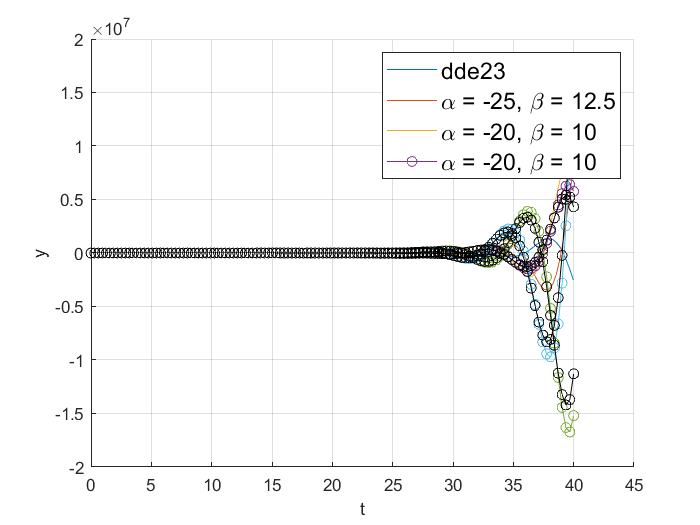

figure
hold on
grid on
xlabel('t')
ylabel('y')
%plot (Im, Imres);
plot(res.x,res.y);
plot (Td, Yd, '-o');
plot (Tdv, Ydv, '-o', 'Color','black');
%plot (Tdt, Ydt, '-o');
%plot (Im, Imres, '-o');
%title('Величина шага h = ',h)
legend({'dde23', '\alpha = -25, \beta = 12.5', '\alpha = -20, \beta = 10', '\alpha = -20, \beta = 10'},'FontSize',14)

%plot (M,(K(1,:)));
%plot (A,(B(1,:)),'--');
%plot (Aa,(Bb(1,:)),'-o');

% figure
% hold on
% grid on
% xlabel('t')
% ylabel('y')
% %plot (Im, Imres);
% %plot(res.x,res.y);
% plot (Td, Yd);
% %plot (Im, Imres, '-o');
% title('Величина шага h = ',h)
% legend('y_1','y_2','y_3')
% %legend('dde23', 'RKC with 2 stages and damp=0.3', "ex. RC with 4 stages")
% %plot (M,(K(1,:)));
% %plot (A,(B(1,:)),'--');
% %plot (Aa,(Bb(1,:)),'-o');